%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% This code is the main program of AK-SeS.
% The code requires a call to the UQLAB toolbox to run.
% The code is used by uncommenting the corresponding limit
% state functions and hyperparameters and running the program
% to complete the calculations. Case 4 requires solidworks2021
% and comsol6.1.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear all
uqlab;

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
D:\software\matlab2023b\toolbox\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



rng(100,'twister')
%The global model is required in example 4
% global model

% pnumber*n is the size of S_{sort};
% nn*n is the size of S_{train}^1;
% nnn*n is the size of S_{cand};
% pft2 is the failure probability;
% r is the beta

% Example 1
% pnumber = 1e2;nn = 5;nnn=1e3;
% n = 2;
% g = @(x) min(3 - x(:,2) + exp(-x(:,1).^2./10) + (x(:,1)./5).^4, ...
%             8 - x(:,1).*x(:,2));

% gg = @(x,y) min(3 - y + exp(-x.^2./10) + (x./5).^4,8 - x.*y);

%Example 2-1
% pnumber = 1e2;nn = 5;nnn=1e3;
% n=2;
% g = @(x) min([0.1.*(x(:,1)-x(:,2)).^2-(x(:,1)+x(:,2))/sqrt(2)+3, ...
%              0.1.*(x(:,1)-x(:,2)).^2+(x(:,1)+x(:,2))/sqrt(2)+3, ...
%              x(:,1)-x(:,2)+3.5.*sqrt(2), ...
%              -x(:,1)+x(:,2)+3.5.*sqrt(2) ...
%              ],[],2);

% gg = @(x,y) min([0.1.*(x-y).^2-(x+y)/sqrt(2)+3, ...
%          0.1.*(x-y).^2+(x+y)/sqrt(2)+3, ...
%          x-y+3.5.*sqrt(2), ...
%          -x+y+3.5.*sqrt(2) ...
%          ],[],2);

% Example 2-2
%pnumber = 1e2;nn = 2;nnn=1e4;
% n = 2;
% g = @(x) 30./((4.*(x(:,1)+2).^2./9 + x(:,2).^2./25).^2+1)+...
%          20./(((x(:,1)-2.5).^2./4 + (x(:,2)-0.5).^2./25).^2+1)-5;

% gg = @(x,y) 30./((4.*(x+2).^2./9 + y.^2./25).^2+1)+...
%  20./(((x-2.5).^2./4 + (y-0.5).^2./25).^2+1)-5;

% Example 2-3
% pnumber = 1e2;nn = 5;nnn=5e3;
% n = 2;
% g = @(x) (x(:,1).*11709.7+78064.4).*(x(:,2).*0.00156+0.0104)-146.14;
% 
% gg = @(x,y) (x.*11709.7+78064.4).*(y.*0.00156+0.0104)-146.14;

% Example 2-4
% n=2;
% g= @(x) 2.5-0.2357.*(x(:,1)-x(:,2)).*3+0.00463.*(x(:,1).*3+x(:,2).*3).^4;

% gg= @(x,y) 2.5-0.2357.*(x.*3-y.*3)+0.00463.*(x.*3+y.*3).^4;

% Example 3
% n = 6;
% % % c1 c2 m r t f
% g_mu = [1 0.1 1 0.5 1 1];
% g_sigma = [0.1 0.01 0.05 0.05 0.2 0.2];
% % % g_mu = [1 0.1 1];
% % % g_sigma = [0.1 0.01 0.2];
% g = @(x) 3*(x(:,4)*g_sigma(4)+g_mu(4))-...
% abs( ...
% 2*(x(:,6)*g_sigma(6)+g_mu(6))./((x(:,1)*g_sigma(1)+g_mu(1))+(x(:,2)*g_sigma(2)+g_mu(2))).* ...
% sin(sqrt(((x(:,1)*g_sigma(1)+g_mu(1))+(x(:,2)*g_sigma(2)+g_mu(2)))./(x(:,3)*g_sigma(3)+g_mu(3))).*(x(:,5)*g_sigma(5)+g_mu(5))./2));
% g = @(x) 3*(0.5)-...
% abs( ...
% 2*(x(:,3).*g_sigma(3)+g_mu(3))./((x(:,1).*g_sigma(1)+g_mu(1))+(x(:,2).*g_sigma(2)+g_mu(2))).* ...
% sin(sqrt(((x(:,1).*g_sigma(1)+g_mu(1))+(x(:,2).*g_sigma(2)+g_mu(2)))./(1)).*(1)./2));

m_pdf = zeros(n,1);
s_pdf = diag(ones(n,1));
t = 0;
n_sigma = 1;
r = sqrt(n+n_sigma*sqrt(2*n)); 
r_set = r;

x1 = truncatedsampling(n*nn,m_pdf',r);
ccc = truncatedsampling(n*nnn,m_pdf',r);
y1=g(x1);
% In the example 4 
% y1 = stent_unit(x1);

r_set = r;
metaOpts.Type = 'Metamodel';
metaOpts.MetaType = 'Kriging';
metaOpts.ExpDesign.Sampling = 'User';
pft_set = zeros(500,1);
pft_set2 = zeros(500,1);
tic
for i = 1:500
    if mod(i,10)==0
        i
    end
    metaOpts.ExpDesign.X = x1;
    metaOpts.ExpDesign.Y = y1;
    mmyKriging = uq_createModel(metaOpts);
    [y_mu,y_sigma] = uq_evalModel(mmyKriging,ccc);
    [cand, index] = sort(abs(y_mu./y_sigma));
    pft = sum(le(y_mu,t))/length(y_mu)
    pft_set2(i,:)=pft;
    [cand2, index2] = sort(abs(y_mu));
    index3=index2(1:n*pnumber);
    r = min(vecnorm(ccc(index3,:),2,2))
    pft1 = cdf('chi2',r^2,n)
    pft2 = (1-pft1)*pft
    pft_set(i,1) = pft2;
    r_set = [r_set; r];
    delta_r = abs(r_set(end)-r_set(end-1))/r_set(end);
    cov = sqrt(1./(length(ccc)-1).*(1./length(ccc).*sum(le(y_mu,t).*(normpdf(ccc)./pft).^2,'all')-pft2.^2))
    if cand(1) < 2
        x1 = [x1; ccc(index(1),:)];
        y1 = [y1; g(ccc(index(1),:))];
        % Example 4
        % y1 = [y1; stent_unit(ccc(index(1),:))];
        ccc = truncatedsampling(n*nnn, m_pdf',r);
    else
        break
    end
end

---   Calculating the Kriging metamodel...                              ---
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.

找到目标函数值更低的可行点。


找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0

r = 2.8614

pft1 = 0.9833

pft2 = 0

cov = NaN

---   Calculating the Kriging metamodel...                              ---
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.

可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0

r = 3.5275

pft1 = 0.9980

pft2 = 0

cov = NaN

---   Calculating the Kriging metamodel...                              ---
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 1.0000e-04

r = 4.0657

pft1 = 0.9997

pft2 = 2.5741e-08

cov = 0.0645

---   Calculating the Kriging metamodel...                              ---
ga stopped because it exceeded options.MaxGenerations.

可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 6.0000e-04

r = 4.5437

pft1 = 1.0000

pft2 = 1.9731e-08

cov = 0.0653

---   Calculating the Kriging metamodel...                              ---
ga stopped because it exceeded options.MaxGenerations.

找到目标函数值更低的可行点。


找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.0037

r = 5.0233

pft1 = 1.0000

pft2 = 1.2269e-08

cov = 0.0266

---   Calculating the Kriging metamodel...                              ---
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.

找到目标函数值更低的可行点。


找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.0399

r = 5.2850

pft1 = 1.0000

pft2 = 3.4333e-08

cov = 0.0091

---   Calculating the Kriging metamodel...                              ---
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.

找到目标函数值更低的可行点。


可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.1704

r = 5.3234

pft1 = 1.0000

pft2 = 1.1962e-07

cov = 0.0046

---   Calculating the Kriging metamodel...                              ---
ga stopped because it exceeded options.MaxGenerations.

找到目标函数值更低的可行点。


可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2115

r = 5.3234

pft1 = 1.0000

pft2 = 1.4846e-07

cov = 0.0042

---   Calculating the Kriging metamodel...                              ---
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.

找到目标函数值更低的可行点。


可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2075

r = 5.3244

pft1 = 1.0000

pft2 = 1.4489e-07

cov = 0.0043

i = 10

---   Calculating the Kriging metamodel...                              ---
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.

找到目标函数值更低的可行点。


可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2131

r = 5.3265

pft1 = 1.0000

pft2 = 1.4712e-07

cov = 0.0042

---   Calculating the Kriging metamodel...                              ---
ga stopped because it exceeded options.MaxGenerations.

可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2077

r = 5.3272

pft1 = 1.0000

pft2 = 1.4290e-07

cov = 0.0043

---   Calculating the Kriging metamodel...                              ---
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.

找到目标函数值更低的可行点。


可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2110

r = 5.3276

pft1 = 1.0000

pft2 = 1.4484e-07

cov = 0.0042

---   Calculating the Kriging metamodel...                              ---
ga stopped because it exceeded options.MaxGenerations.

可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2163

r = 5.3280

pft1 = 1.0000

pft2 = 1.4818e-07

cov = 0.0042

---   Calculating the Kriging metamodel...                              ---
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.

找到目标函数值更低的可行点。


可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2126

r = 5.3287

pft1 = 1.0000

pft2 = 1.4511e-07

cov = 0.0042

---   Calculating the Kriging metamodel...                              ---
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.

可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2117

r = 5.3289

pft1 = 1.0000

pft2 = 1.4432e-07

cov = 0.0042

---   Calculating the Kriging metamodel...                              ---
ga stopped because it exceeded options.MaxGenerations.

找到目标函数值更低的可行点。


可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2134

r = 5.3291

pft1 = 1.0000

pft2 = 1.4535e-07

cov = 0.0042

---   Calculating the Kriging metamodel...                              ---
ga stopped because it exceeded options.MaxGenerations.

找到目标函数值更低的可行点。


可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2130

r = 5.3292

pft1 = 1.0000

pft2 = 1.4499e-07

cov = 0.0041

---   Calculating the Kriging metamodel...                              ---
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.

找到目标函数值更低的可行点。


可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2154

r = 5.3293

pft1 = 1.0000

pft2 = 1.4652e-07

cov = 0.0042

---   Calculating the Kriging metamodel...                              ---
ga stopped because it exceeded options.MaxGenerations.

找到目标函数值更低的可行点。


可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2145

r = 5.3294

pft1 = 1.0000

pft2 = 1.4583e-07

cov = 0.0041

i = 20

---   Calculating the Kriging metamodel...                              ---
ga stopped because it exceeded options.MaxGenerations.

找到目标函数值更低的可行点。


可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2144

r = 5.3298

pft1 = 1.0000

pft2 = 1.4548e-07

cov = 0.0042

---   Calculating the Kriging metamodel...                              ---
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.

找到目标函数值更低的可行点。


可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2154

r = 5.3301

pft1 = 1.0000

pft2 = 1.4589e-07

cov = 0.0042

---   Calculating the Kriging metamodel...                              ---
ga stopped because it exceeded options.MaxGenerations.

找到目标函数值更低的可行点。


可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2141

r = 5.3306

pft1 = 1.0000

pft2 = 1.4466e-07

cov = 0.0042

---   Calculating the Kriging metamodel...                              ---
ga stopped because it exceeded options.MaxGenerations.

找到目标函数值更低的可行点。


可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2154

r = 5.3306

pft1 = 1.0000

pft2 = 1.4552e-07

cov = 0.0041

---   Calculating the Kriging metamodel...                              ---
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.

可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2144

r = 5.3307

pft1 = 1.0000

pft2 = 1.4481e-07

cov = 0.0042

---   Calculating the Kriging metamodel...                              ---
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.

找到目标函数值更低的可行点。


可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2139

r = 5.3318

pft1 = 1.0000

pft2 = 1.4361e-07

cov = 0.0042

---   Calculating the Kriging metamodel...                              ---
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.

可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2168

r = 5.3320

pft1 = 1.0000

pft2 = 1.4540e-07

cov = 0.0042

---   Calculating the Kriging metamodel...                              ---
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.

可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2121

r = 5.3320

pft1 = 1.0000

pft2 = 1.4224e-07

cov = 0.0041

---   Calculating the Kriging metamodel...                              ---
ga stopped because it exceeded options.MaxGenerations.

可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2161

r = 5.3329

pft1 = 1.0000

pft2 = 1.4424e-07

cov = 0.0042

---   Calculating the Kriging metamodel...                              ---
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.

找到目标函数值更低的可行点。


可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2197

r = 5.3329

pft1 = 1.0000

pft2 = 1.4664e-07

cov = 0.0041

i = 30

---   Calculating the Kriging metamodel...                              ---
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.

可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2212

r = 5.3331

pft1 = 1.0000

pft2 = 1.4750e-07

cov = 0.0041

---   Calculating the Kriging metamodel...                              ---
ga stopped because it exceeded options.MaxGenerations.

找到目标函数值更低的可行点。


可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2160

r = 5.3331

pft1 = 1.0000

pft2 = 1.4399e-07

cov = 0.0041

---   Calculating the Kriging metamodel...                              ---
ga stopped because it exceeded options.MaxGenerations.

可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>
---   Calculation finished!                                             ---


pft = 0.2133

r = 5.3337

pft1 = 1.0000

pft2 = 1.4171e-07

cov = 0.0041

toc

历时 6.633914 秒。


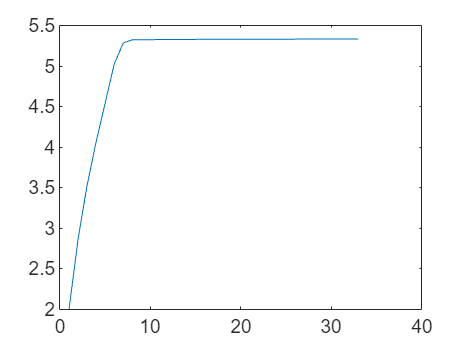

plot(1:length(r_set),r_set);

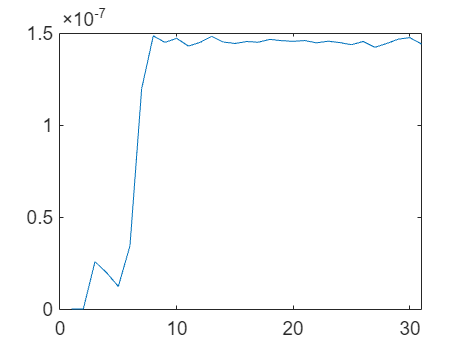

plot(1:i-1,pft_set(1:i-1));

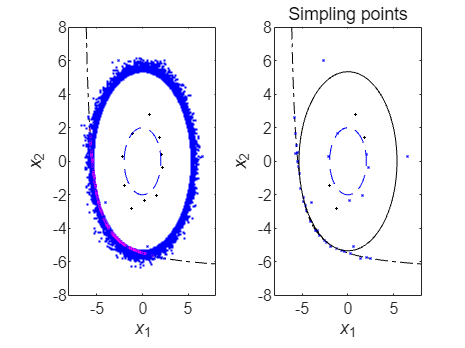

subplot(1,2,1)
fimplicit(gg,[-8 8 -8 8],"LineStyle","-.","Color",'k');
xlim([-8 8]);
ylim([-8 8]);
xlabel('\itx_{\rm1}');
ylabel('\itx_{\rm2}');
hold on
scatter(x1(1:n*nn,1),x1(1:n*nn,2),2,'k','+');
hold on
scatter(x1(nn*n+1:end,1),x1(nn*n+1:end,2),2,'blue','x');

g_circle = @(x,y) x.^2+y.^2-r_set(1,1).^2;
g_circle2 = @(x,y) x.^2+y.^2-r_set(end,1).^2;
fimplicit(g_circle,[-8,8],'LineWidth',0.5,'LineStyle','--','Color','b');
fimplicit(g_circle2,[-8,8],'LineWidth',0.5,'LineStyle','-','Color','k');

sampling_point2 = ccc(index2(n*pnumber+1:end),:);
scatter(ccc(index2(n*pnumber+1:end),1),ccc(index2(n*pnumber+1:end),2),0.2,'blue','.');
hold on
sampling_point = ccc(index3,:);
scatter(sampling_point(:,1),sampling_point(:,2),2,'LineWidth',0.2,'MarkerEdgeColor','magenta','Marker','o');
hold off

subplot(1,2,2)
fimplicit(gg,[-8 8 -8 8],"LineStyle","-.","Color",'k');
xlim([-8 8]);
ylim([-8 8]);
xlabel('\itx_{\rm1}');
ylabel('\itx_{\rm2}');
title('Simpling points');
hold on
scatter(x1(1:n*2,1),x1(1:n*2,2),2,'k','+');
scatter(x1(2*n+1:end,1),x1(2*n+1:end,2),2,'blue','x');

g_circle = @(x,y) x.^2+y.^2-r_set(1,1).^2;
g_circle2 = @(x,y) x.^2+y.^2-r_set(end,1).^2;
fimplicit(g_circle,[-8,8],'LineWidth',0.5,'LineStyle','--','Color','b');
fimplicit(g_circle2,[-8,8],'LineWidth',0.5,'LineStyle','-','Color','k');
hold off